## Программа расчета эффективности планарно-волноводных антен

### Установка первоначальных данных

Излучатель

Opt_ource(1).P = 0.10; % Мощность излучения в Вт
Opt_ource(1).lambda_max = 365; % Максимум излучения нм
Opt_ource(1).lambda_FWHM = 10; % Полуширина линии нм

N_ph = 10;

#### Характеристики ПВА

Материал ПВА

% ПММА
PFA.n = 1.52;


Характеристики люминофора

% Пока без характеристик
Lum_ = NaN;

Характеристики выводной части (приемника)

d_f = 10;

Характеристики границы

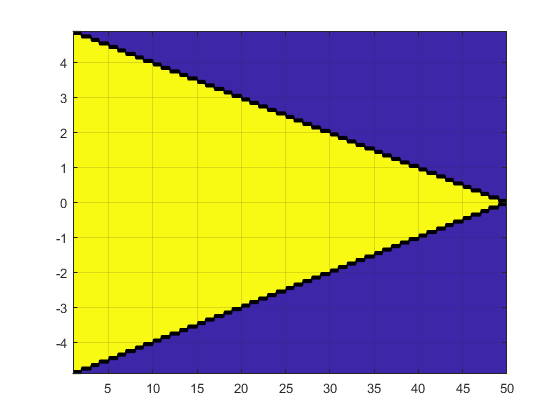

% Формируем координаты расчета
x = 1:0.1:100;
clear border_p
global border_p;
border_p = [d_f / 2, -0.1];

x = x (is_PFA(x,0));
y = -max(forma_border_L(x).*is_PFA(x,0)):0.1:max(forma_border_L(x).*is_PFA(x,0));

[X,Y] = meshgrid(x,y);
M = is_PFA(X,Y);
figure
contourf(X,Y,M)
grid on

### Расчет

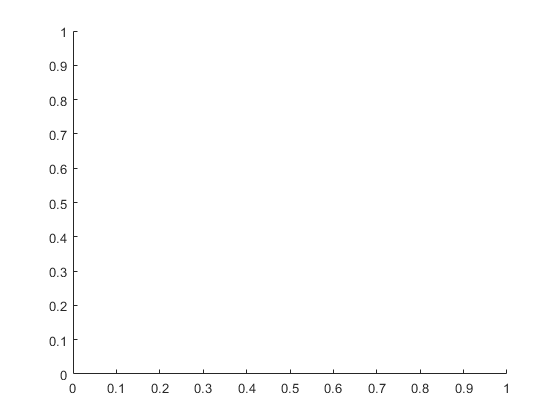

Error using matlab.graphics.chart.primitive.Surface
Invalid parameter/value pair arguments.

Error in surf (line 145)
hh = matlab.graphics.chart.primitive.Surface(allargs{:});

for kx = 1:size(X,1)
    for ky = 1:size(X,2)
        if is_PFA(X(kx,ky), Y(kx,ky))
           for n = 1:N_ph
               alpha = rand()*pi
               
           end
        end
    end
end

figure
surf(X,Y,M1)

function result = forma_border_p(x)
%% Форма границы (полином)
global border_p
result = 0;
for i = 1:numel(border_p)
    result = result + border_p(i) .* x .^ (i-1);
end
end

function result = forma_border_L(x)
%% Форма левой границы
result = forma_border_p(x);
end
function result = forma_border_R(x)
%% Форма правой границы
result = -forma_border_p(x);
end

function result = is_PFA(x, y)
%% Проверка относится ли точка к антеннес
result = and (y >= forma_border_R(x), y <= forma_border_L(x));
end

function varargout = border_crossing_detection(varargin)
%% Определение точки пересечения с границами
if nargin >= 3
    x = varargin{1};
    y = varargin{2};
    alpha = varargin{3};
else
    varargout{1} = false;
    return 
end
if nargin >= 3
    border_name = varargin{4};
end


end